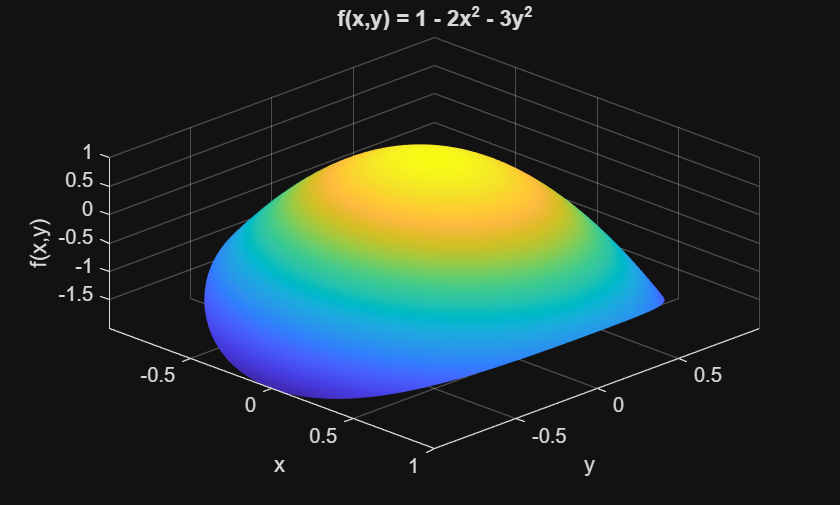

clear;
clc;
close all;

theta = linspace(0, 2*pi, 100);
r = linspace(0, 1, 100);

[Theta, R] = meshgrid(theta, r);

X = R .* cos(Theta);
Y = R .* sin(Theta);

Z = 1 - 2.*X.^2 - 3.*Y.^2;

figure;

surf(X, Y, Z);

shading interp;
colormap parula;

xlabel('x');
ylabel('y');
zlabel('f(x,y)');

title('f(x,y) = 1 - 2x^2 - 3y^2');

grid on;
axis tight;

view(45, 45);

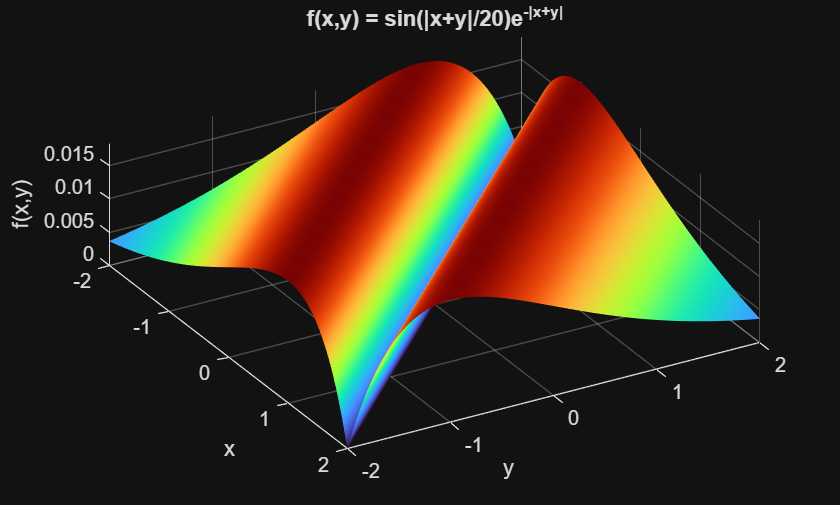


x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);

[X, Y] = meshgrid(x, y);

Z = sin(abs(X + Y)./20) .* exp(-abs(X + Y));

figure;

surf(X, Y, Z);

shading interp;
colormap turbo;

xlabel('x');
ylabel('y');
zlabel('f(x,y)');

title('f(x,y) = sin(|x+y|/20)e^{-|x+y|}');

grid on;
axis tight;

view(60, 60);

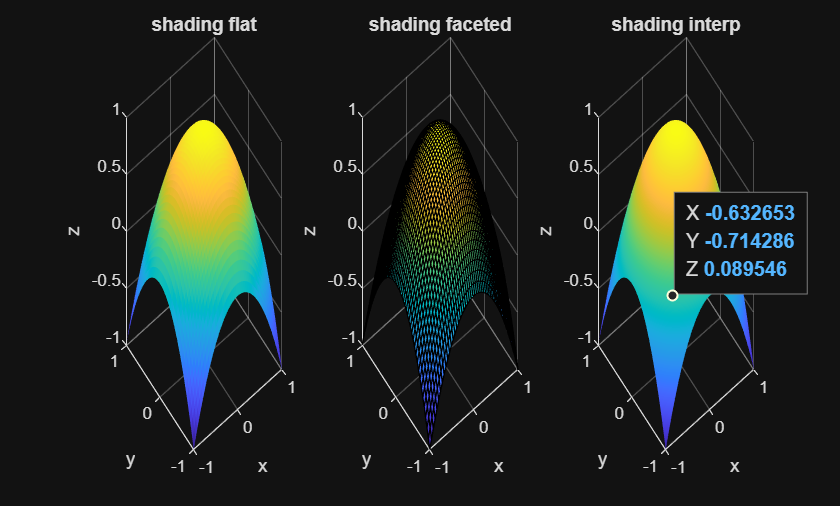

clear;
clc;
close all;

x = linspace(-1, 1, 50);
y = linspace(-1, 1, 50);

[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

figure;

subplot(1,3,1);
surf(X, Y, Z);
shading flat;
title('shading flat');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

subplot(1,3,2);
surf(X, Y, Z);
shading faceted;
title('shading faceted');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

subplot(1,3,3);
surf(X, Y, Z);
shading interp;
title('shading interp');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;